% house_simulate(timespan, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation)
[T, Y, debug] = house_simulate([1, 24 * 60 * 60], 5, 10, 25, 1, 0.5)

T = 	1.0e+04 *

    0.0001
    0.0434
    0.0868
    0.1301
    0.1735
    0.2065
    0.2395
    0.2725
    0.3055
    0.3385


Y =   291.0000  291.0000
  291.0791  290.9685
  291.0809  290.9372
  290.9062  290.9064
  290.7956  290.8756
  290.8980  290.8520
  290.9255  290.8287
  290.8192  290.8058
  290.7389  290.7830
  290.8053  290.7602


debug = 	1.0e+05 *

         0         0         0         0
         0    0.0015         0   -0.0403
   -0.0003    0.0015         0   -0.0395
    0.0009    0.0015   -0.0001   -0.0388
   -0.0925    0.0014    0.0034   -0.0319
   -0.8102    0.0012    0.0302   -0.0300
   -4.2377    0.0006    0.1581   -0.0274
    7.2164    0.0027   -0.2694   -0.0274
   -0.0001    0.0015         0   -0.0402
   -0.0000    0.0015   -0.0000   -0.0401


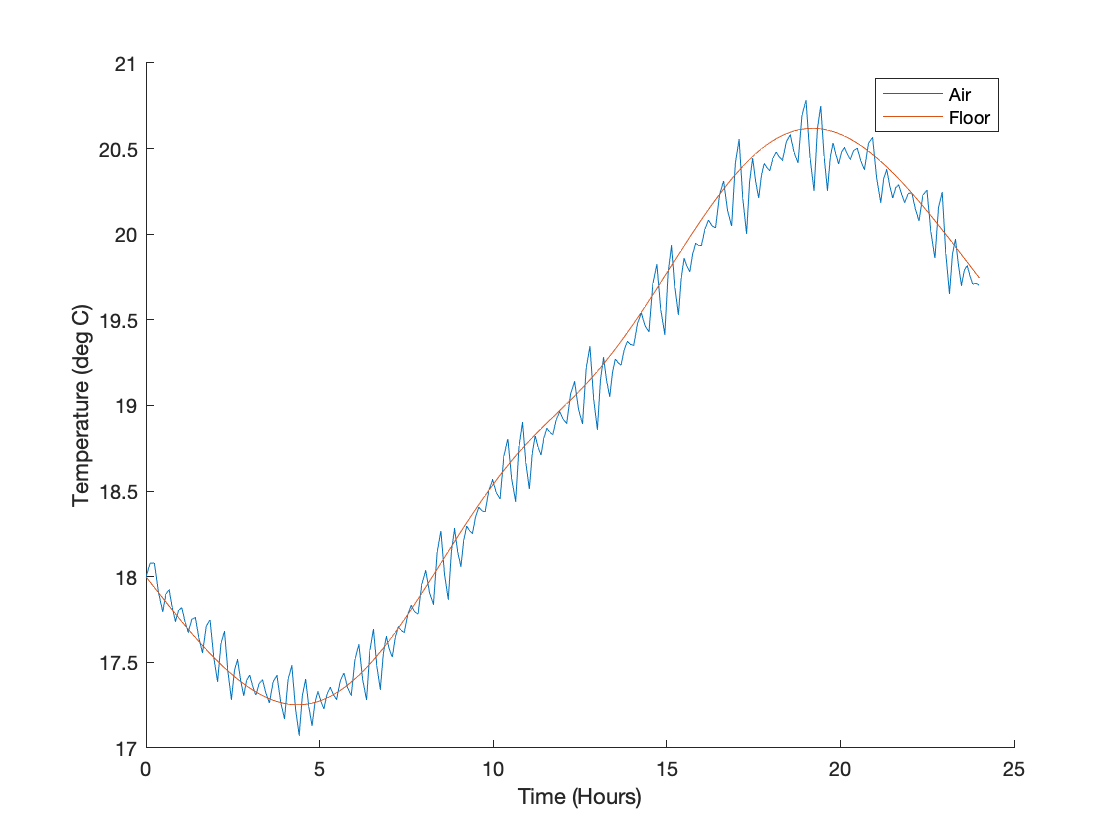

clf; hold on;

plot(T / (60 * 60), Y(:, 1) - 273);
plot(T / (60 * 60), Y(:, 2) - 273);
legend("Air", "Floor");
xlabel("Time (Hours)");
ylabel("Temperature (deg C)");

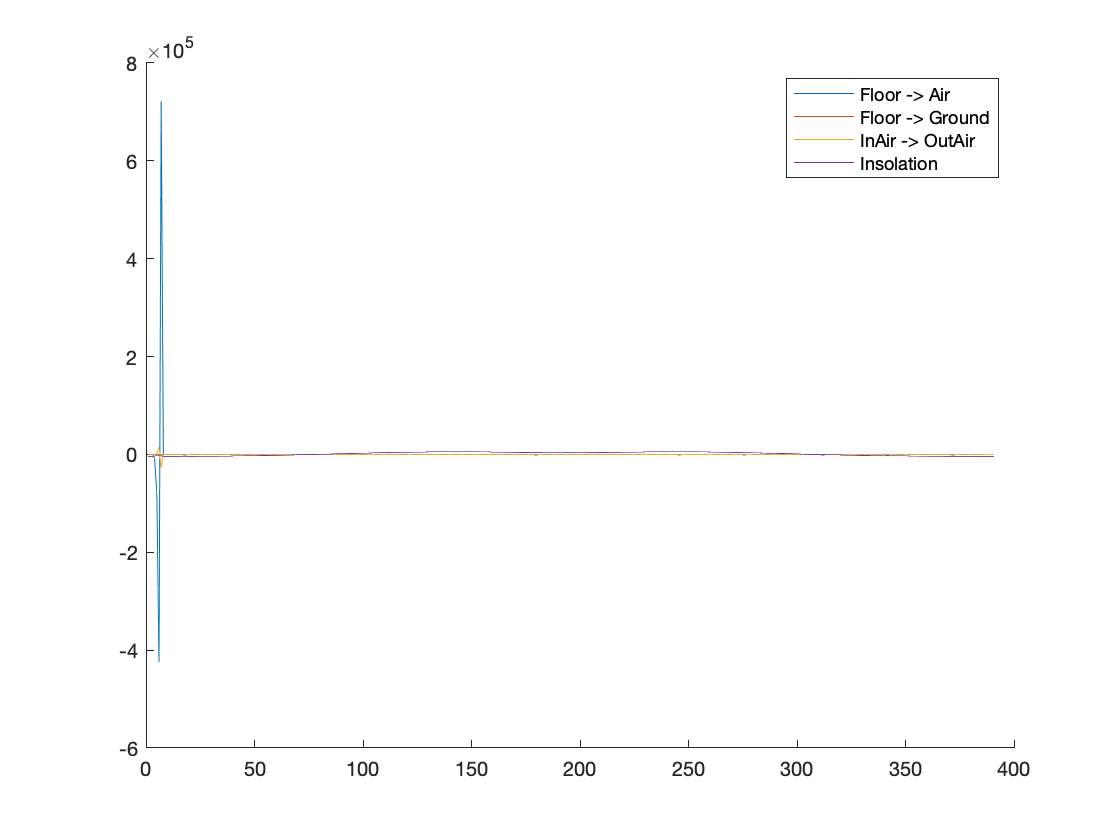

figure; clf; hold on;
%        debug(end + 1, :) = [dUdt_floor_to_air, dUdt_floor_to_ground, dUdt_air_to_air, dUdt_insolation];
% The first item in `debug` is all zeros, so ignore it
plot(debug(2:end, 1));
plot(debug(2:end, 2));
plot(debug(2:end, 3));
plot(debug(2:end, 4));
legend("Floor -> Air", "Floor -> Ground", "InAir -> OutAir", "Insolation");